# Tensor Decompositions - Mohammad Sadra Hosseini - 401110448

## Q1.

notation in report is:


$$Y = A X + E
$$


1.1

for this part we can use equations 4.12 and 4.13 Cichocki and run algorithm for many times:


$$A \leftarrow [YX^T(XX^T)^\dagger]_+$$



$$X \leftarrow [(A^TA)^\dagger A^T Y]_+$$



$$[.]_+ = max[\epsilon, .]$$
 

and dagger used for moore-penrose pseudo-inverse.

1.2

for this part we can use equations 3.8 and 3.9 Cichocki and run algorithm untill convergence(run algorithm for many times):


$$a_{ij} \leftarrow a_{ij} \frac{[YX^T]_{ij}}{[AXX^T]_{ij} + \epsilon}$$



$$x_{jt} \leftarrow x_{jt} \frac{[A^TY]_{jt}}{[A^TAX]_{jt} + \epsilon}$$


we can use pointwise division for above matrices.

1.3.1

first we must generate B, C & E matrices from uniform distribution using rand function:

clc, clear all
B = rand(6, 3);
C = rand(3, 4);
E = rand(6, 4);

1.3.2

for every SNR, there is a matrix A that we save it in A tensor.

A = zeros(6, 4, 5);
SNR = [-10, 0, 10, 30, 50];
for i = 1 : length(SNR)
    alpha = norm(B * C, 'fro') / ((10 ^ (SNR(i) / 20)) * norm(E, 'fro'));
    fprintf('alpha for SNR = %i is %i\n', SNR(i) , alpha);
    A(:, :, i) = B * C + alpha * E;
end

alpha for SNR = -10 is 3.847537e+00
alpha for SNR = 0 is 1.216698e+00
alpha for SNR = 10 is 3.847537e-01
alpha for SNR = 30 is 3.847537e-02
alpha for SNR = 50 is 3.847537e-03


1.3.3

first define two vectors for saving errors. Then generate B0 and C0 using random function matlab for one source problem. for matlab's nmf built in functions:

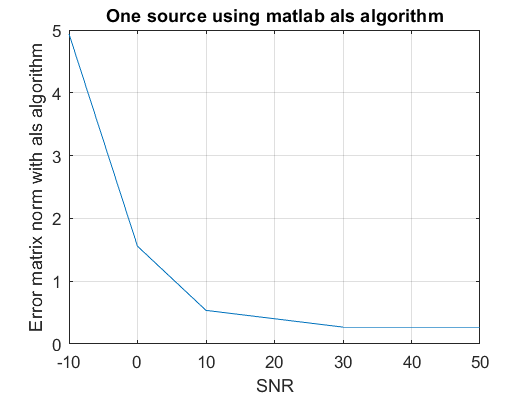

error_nmf_als = zeros(5, 1);
error_nmf_multiplicative = zeros(5, 1);
B0 = rand(6, 1);
C0 = rand(1, 4);
for i = 1 : 5
    [B, C] = nnmf(A(:, :, i), 1, 'algorithm', 'als', 'w0', B0, 'h0', C0);
    error_nmf_als(i) = norm(A(:, :, i) - B * C, 'fro');
    [B, C] = nnmf(A(:, :, i), 1, 'algorithm', 'mult', 'w0', B0, 'h0', C0);
    error_nmf_multiplicative(i) = norm(A(:, :, i) - B * C, 'fro');
end

figure;
SNR = [-10, 0, 10, 30, 50];
plot(SNR, error_nmf_als);
grid on
xlabel('SNR');
ylabel('Error matrix norm with als algorithm');
title('One source using matlab als algorithm');

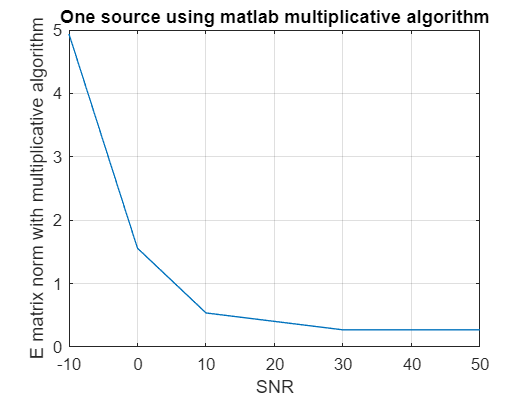

figure;
plot(SNR, error_nmf_multiplicative);
grid on;
xlabel('SNR');
ylabel('E matrix norm with multiplicative algorithm');
title('One source using matlab multiplicative algorithm');

and for my nmf algorithms:

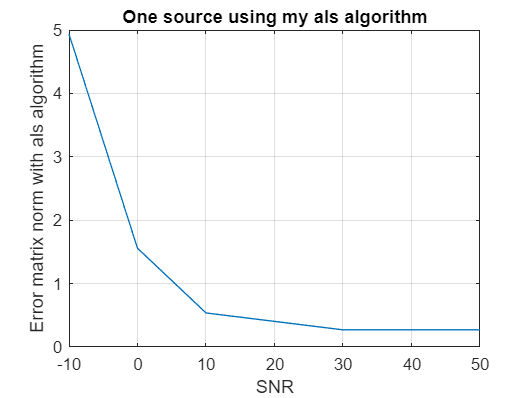

error_nmf_als = zeros(5, 1);
error_nmf_multiplicative = zeros(5, 1);
B0 = rand(6, 1);
C0 = rand(1, 4);
for i = 1 : 5
    [B, C] = nmf_als(A(:, :, i), 1, B0, C0);
    error_nmf_als(i) = norm(A(:, :, i) - B * C, 'fro');
    [B, C] = nmf_multiplicative(A(:, :, i), 1, B0, C0);
    error_nmf_multiplicative(i) = norm(A(:, :, i) - B * C, 'fro');
end

figure;
SNR = [-10, 0, 10, 30, 50];
plot(SNR, error_nmf_als);
grid on
xlabel('SNR');
ylabel('Error matrix norm with als algorithm');
title('One source using my als algorithm');

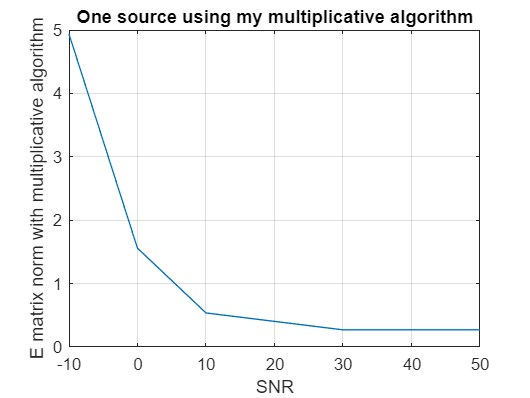

figure;
plot(SNR, error_nmf_multiplicative);
grid on;
xlabel('SNR');
ylabel('E matrix norm with multiplicative algorithm');
title('One source using my multiplicative algorithm');

as you can see from graphs, results of my algorithms and results of matlab's algorithms are approximately same.

1.3.4

repeat = 10;
SNR = [-10, 0, 10, 30, 50];
number_of_sources = [2, 3, 4]

number_of_sources =      2     3     4


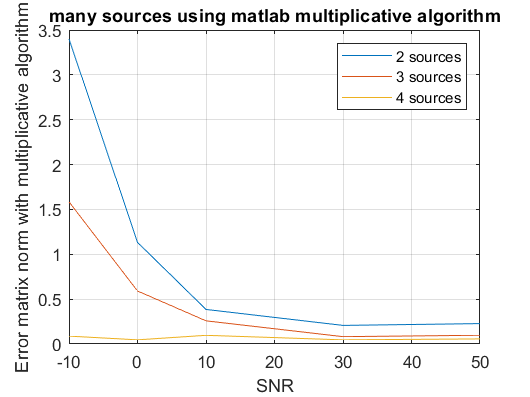

figure;
for i = 1 : length(number_of_sources)
    error_nmf_multiplicative = zeros(5, 1);
    for j = 1 : 5
        for k = 1 : repeat
            B0 = rand(6, number_of_sources(i));
            C0 = rand(number_of_sources(i), 4);
            [B, C] = nnmf(A(:, :, j), number_of_sources(i), 'algorithm', 'mult', 'w0', B0, 'h0', C0);
            error_nmf_multiplicative(j) = error_nmf_multiplicative(j) + norm(A(:, :, j) - B * C, 'fro');
        end
    end
    error_nmf_multiplicative = error_nmf_multiplicative / repeat;
    grid on
    xlabel('SNR');
    ylabel('Error matrix norm with multiplicative algorithm');
    title('many sources using matlab multiplicative algorithm');
    plot(SNR, error_nmf_multiplicative);
    hold on
end
legend('2 sources', '3 sources', '4 sources');

matlab's als algorithm:

figure;
for i = 1 : length(number_of_sources)
    error_nmf_als = zeros(5, 1);
    for j = 1 : 5
        for k = 1 : repeat
            B0 = rand(6, number_of_sources(i));
            C0 = rand(number_of_sources(i), 4);
            [B, C] = nnmf(A(:, :, j), number_of_sources(i), 'algorithm', 'als', 'w0', B0, 'h0', C0);
            error_nmf_als(j) = error_nmf_als(j) + norm(A(:, :, j) - B * C, 'fro');
        end
    end
    error_nmf_als = error_nmf_als / repeat;
    grid on
    xlabel('SNR');
    ylabel('Error matrix norm with als algorithm');
    title('many sources using matlab als algorithm');
    plot(SNR, error_nmf_als);
    hold on
end

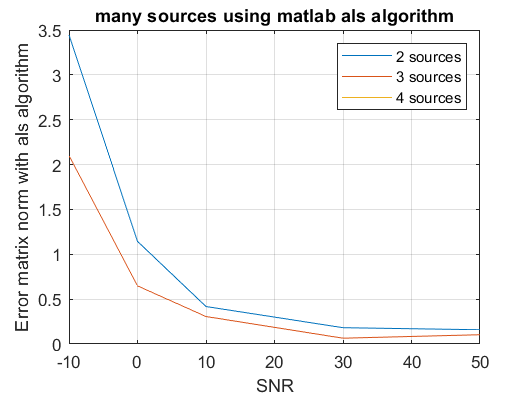

legend('2 sources', '3 sources', '4 sources');

my multiplicative algorithm:

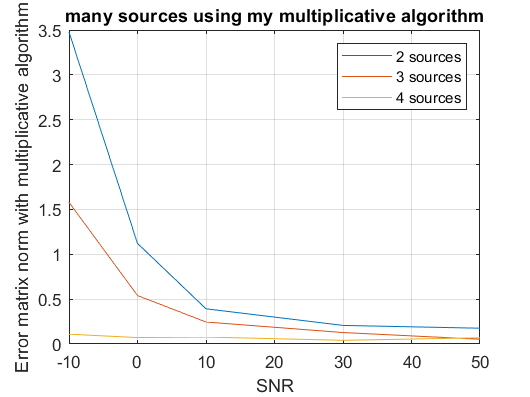

figure;
for i = 1 : length(number_of_sources)
    error_nmf_multiplicative = zeros(5, 1);
    for j = 1 : 5
        for k = 1 : repeat
            B0 = rand(6, number_of_sources(i));
            C0 = rand(number_of_sources(i), 4);
            [B, C] = nmf_multiplicative(A(:, :, j), number_of_sources(i), B0, C0);
            error_nmf_multiplicative(j) = error_nmf_multiplicative(j) + norm(A(:, :, j) - B * C, 'fro');
        end
    end
    error_nmf_multiplicative = error_nmf_multiplicative / repeat;
    grid on
    xlabel('SNR');
    ylabel('Error matrix norm with multiplicative algorithm');
    title('many sources using my multiplicative algorithm');
    plot(SNR, error_nmf_multiplicative);
    hold on
end
legend('2 sources', '3 sources', '4 sources');

my als algorithm:

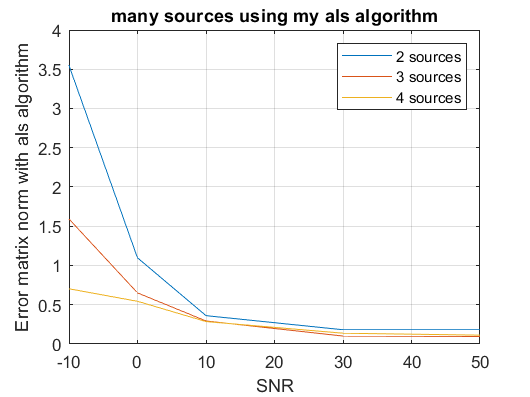

figure;
for i = 1 : length(number_of_sources)
    error_nmf_als = zeros(5, 1);
    for j = 1 : 5
        for k = 1 : repeat
            B0 = rand(6, number_of_sources(i));
            C0 = rand(number_of_sources(i), 4);
            [B, C] = nmf_als(A(:, :, j), number_of_sources(i), B0, C0);
            error_nmf_als(j) = error_nmf_als(j) + norm(A(:, :, j) - B * C, 'fro');
        end
    end
    error_nmf_als = error_nmf_als / repeat;
    grid on
    xlabel('SNR');
    ylabel('Error matrix norm with als algorithm');
    title('many sources using my als algorithm');
    plot(SNR, error_nmf_als);
    hold on
end
legend('2 sources', '3 sources', '4 sources');

as you can see from above graphs, if SNR increase that means error will decrease. also if we increase the number of components, error will decrease that means probably we have four components or more. also from the results of these two algorithms, that seems multiplicative is better algorithm for this problem.

## Q2.

first we must load our dataset:

clc, clear all
load('swimmer.mat');

L = length(A);
[m, n] = size(A{1});
data = zeros(L, m * n);

then save every matrix as a vector in a 256 * 136 matrix:

for i = 1 : L
    data(i, :) = reshape(A{i}, 1, m * n);
end

for finding the number of sources that minimize the error of our decomposition, first calculate error and then plot error versus number of sources.

als algorithm:

error_nmf_als = zeros(50, 1);
max_number_of_sources = 50;
for j = 1 : max_number_of_sources
    [B, C] = nnmf(data, j, 'algorithm', 'als');
    error_nmf_als(j) = norm(data - B * C, 'fro');
end

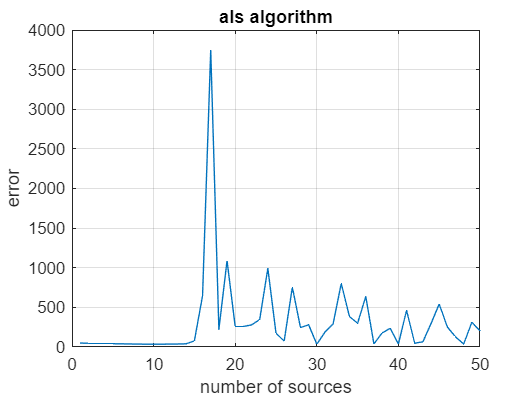


figure;
j = linspace(1, max_number_of_sources, max_number_of_sources);
plot(j, error_nmf_als);
title('als algorithm');
grid on;
xlabel('number of sources');
ylabel('error');

multiplicative algorithm:

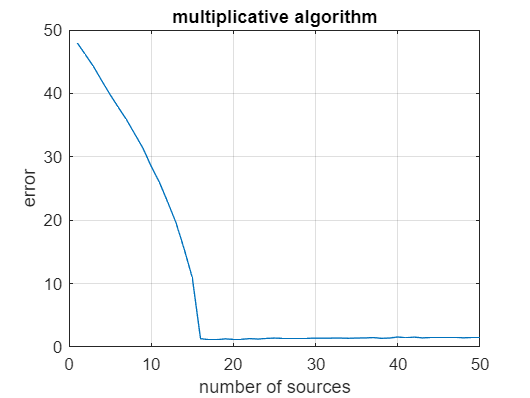

error_nmf_multiplicative = zeros(50, 1);
max_number_of_sources = 50;
for j = 1 : max_number_of_sources
    [B, C] = nnmf(data, j, 'algorithm', 'mult');
    error_nmf_multiplicative(j) = norm(data - B * C, 'fro');
end

figure;
j = linspace(1, max_number_of_sources, max_number_of_sources);
plot(j, error_nmf_multiplicative);
title('multiplicative algorithm');
grid on;
xlabel('number of sources');
ylabel('error');

from above graphs we understand als algorithm is not an appropriate algorithm for this problem because the errors we get from this algorithm is very bigger than multiplicative algorithm.

as we can see from multiplicative algorithm error graph, if the number of sources be larger than 17, then error estimately constant.

I run below code for 17 till 23 for my self and in my opinion, output for 17 sources was better and more rational than others. But outputs untill 19 is very same to 17 sources.

now plot the different positions of hands and feets:

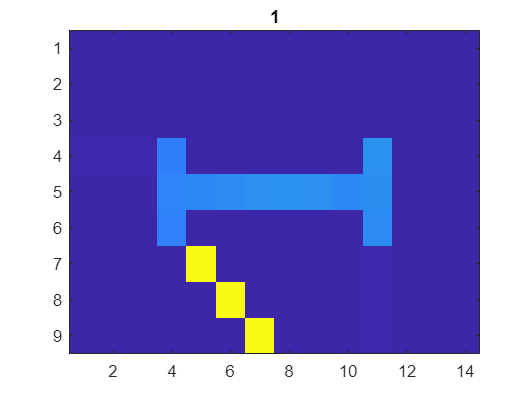

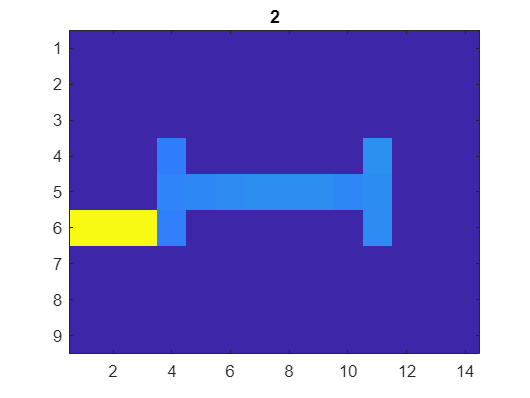

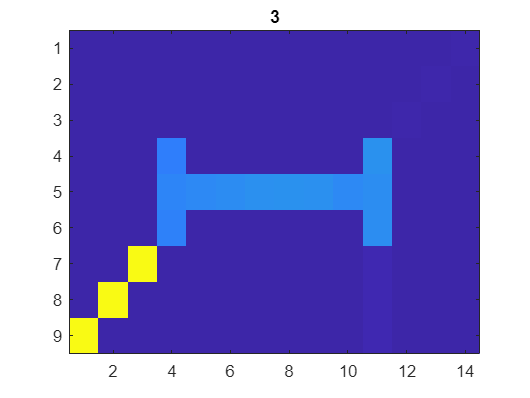

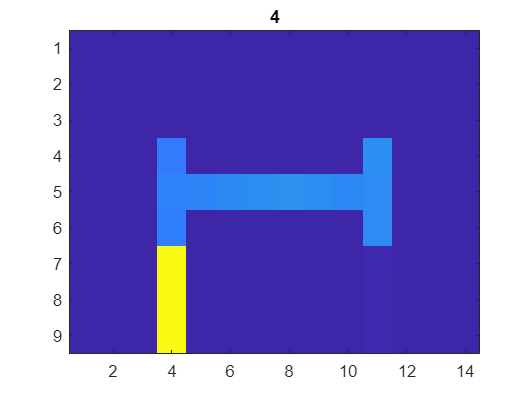

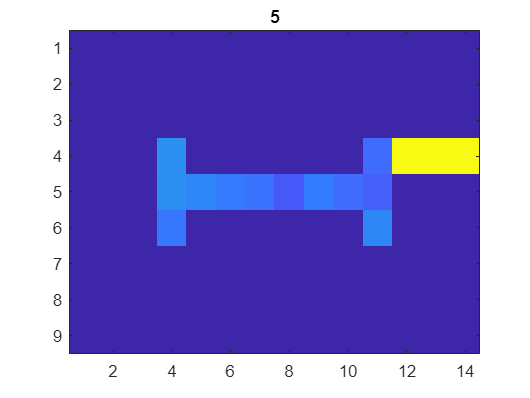

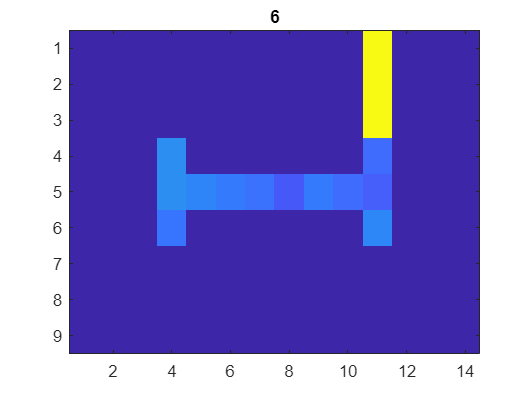

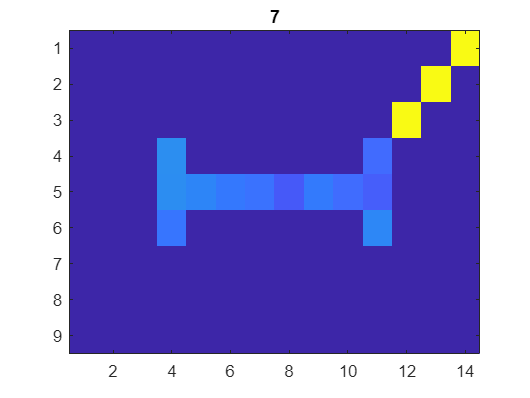

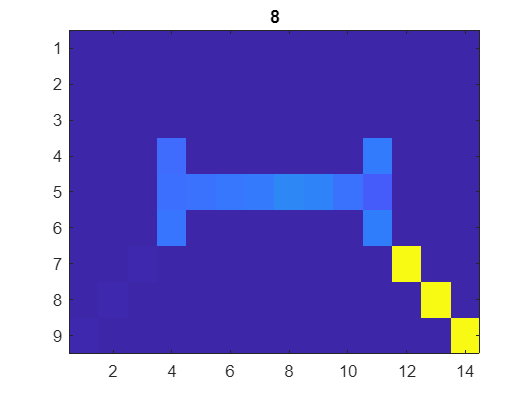

J = 17;
[B, C] = nnmf(data, J, 'algorithm', 'mult');

for j = 1 : J
    figure;
    imagesc(reshape(C(j, :), 9, 14));
    title([num2str(j)]);
end